# TF estimating, and PID Tuning Script

## Importing Table

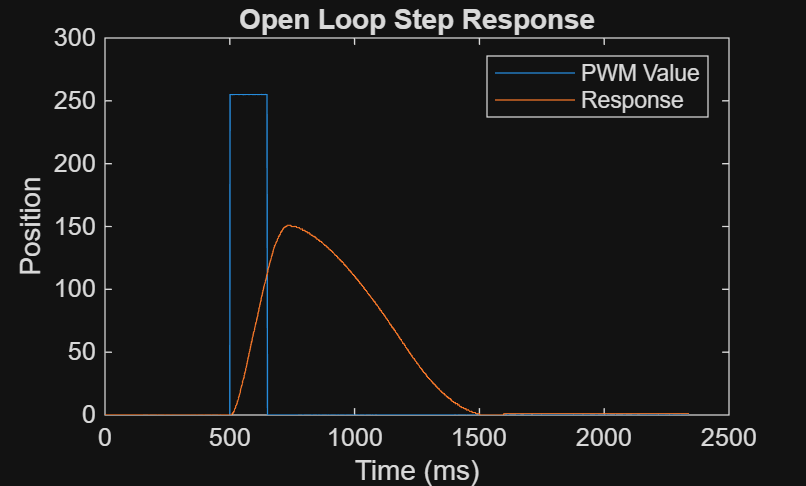

step_pwm = readtable("open_loop.csv");
figure;
plot(step_pwm.time, step_pwm.pwmValue, step_pwm.time, step_pwm.position);
title("Open Loop Step Response");
xlabel('Time (ms)') 
ylabel('Position') 
legend('PWM Value', 'Response');

T = readtable("open_loop.csv");

## Removing Offset

t_raw = T.time(:) / 1000;         % seconds (time is in ms)
u_raw = T.pwmValue(:);            % PWM command (0..255)
y_raw = T.position(:);            % encoder counts

% Ensure column vectors + sorted time
[t_raw, idx] = sort(t_raw);
u_raw = u_raw(idx);
y_raw = y_raw(idx);

%% 2) Resample to uniform Ts
Ts = median(diff(t_raw));          % ~0.001 s
t = (t_raw(1):Ts:t_raw(end))';

% Input as zero-order hold, output as linear interpolation
u = interp1(t_raw, u_raw, t, "previous", "extrap");
y = interp1(t_raw, y_raw, t, "linear",   "extrap");

% convert counts -> radians
CPR = 2048;                        % <-- CHANGE (counts per revolution)
y = (2*pi/CPR) * y;                % radians

% trim to a clean window (optional but helps)
% Include a bit before the pulse and enough time after to see ring-down
tStart = 0.0;
tEnd   = t(end);
keep = (t >= tStart) & (t <= tEnd);

t = t(keep);
u = u(keep);
y = y(keep);

%% detrend / remove offsets
u = u - u(1);
y = y - y(1);

% If you want input in "duty" instead of 0..255:
u = u / 255;

% build iddata
data = iddata(y, u, Ts, "TimeUnit","s");
data.OutputName = "\theta";
data.InputName  = "u";

## Estimating, Curve Fitting

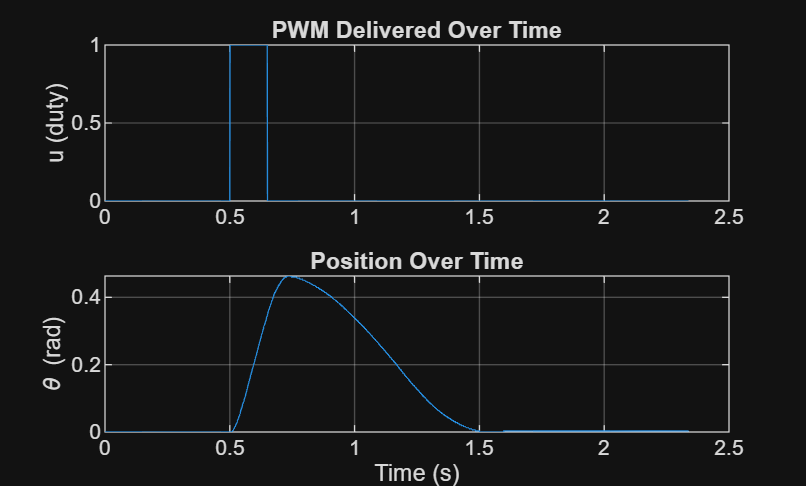

% Plotting cleaned up data
figure;
subplot(2,1,1);
plot(t,u);
grid on;
ylabel("u (duty)");
title("PWM Delivered Over Time");

subplot(2,1,2);
plot(t,y);
grid on;
ylabel("\theta (rad)");
xlabel("Time (s)");
title("Position Over Time");

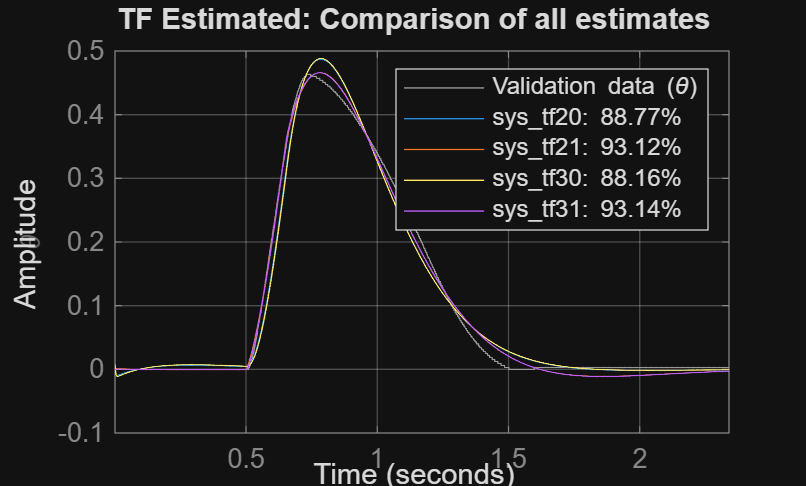


% Estimate models
sys_tf20 = tfest(data, 2, 0);
sys_tf21 = tfest(data, 2, 1);
sys_tf30 = tfest(data, 3, 0);
sys_tf31 = tfest(data, 3, 1);

figure; compare(data, sys_tf20, sys_tf21,sys_tf30,sys_tf31); grid on;
title("TF Estimated: Comparison of all estimates");

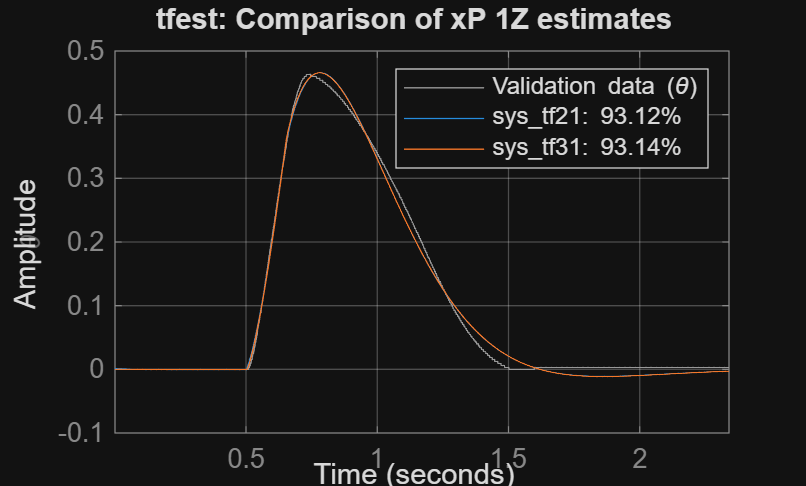


figure; compare(data, sys_tf21, sys_tf31); grid on;
title("tfest: Comparison of xP 1Z estimates");

## Residuals

% figure; resid(data, sys_tf20); grid on; title("Residuals (2p 0z)");
% figure; resid(data, sys_tf21); grid on; title("Residuals (2p 1z)");
% figure; bode(sys_tf20, sys_tf21, sys_tf31); grid on; legend("2p0z","2p1z", "3p1z");

## Display Selected System Stats

disp("Select 2 poles 1 zero as best fit model");

Select 2 poles 1 zero as best fit model


sys_tf21


sys_tf21 =
 
  From input "u" to output "\theta":
    1.159 s + 32.51
  --------------------
  s^2 + 6.95 s + 20.58
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 93.12%                   
FPE: 0.0001164, MSE: 0.0001158                   
 
Model Properties


disp('Damping / natural frequencies for 2p1z model:');

Damping / natural frequencies for 2p1z model:


damp(sys_tf21)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.47e+00 + 2.92e+00i     7.66e-01       4.54e+00         2.88e-01    
 -3.47e+00 - 2.92e+00i     7.66e-01       4.54e+00         2.88e-01    


## Plot Selected System

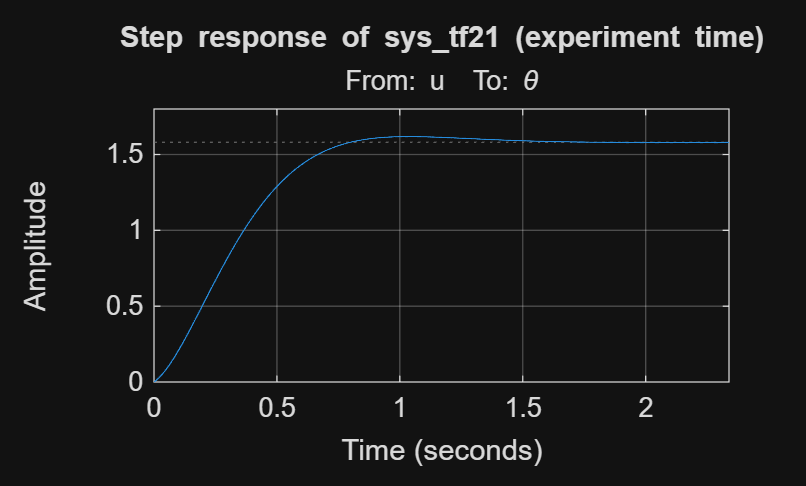

figure;
step(sys_tf21, t);
grid on;
title('Step response of sys\_tf21 (experiment time)');

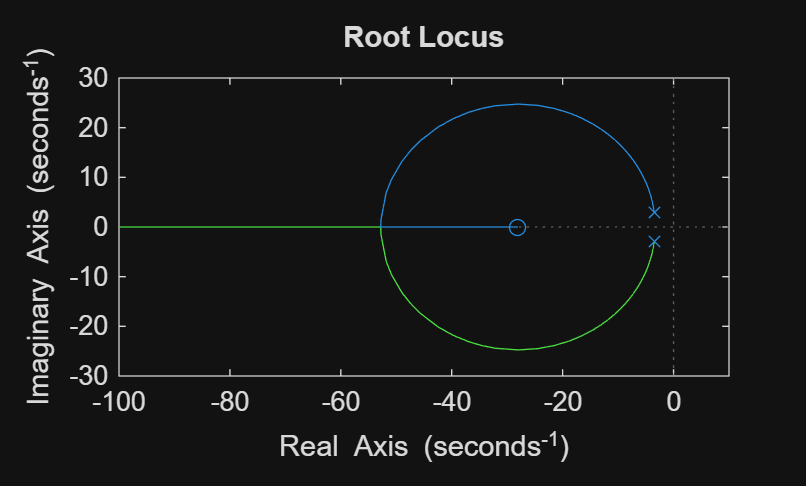

figure;

rlocusplot(sys_tf21);

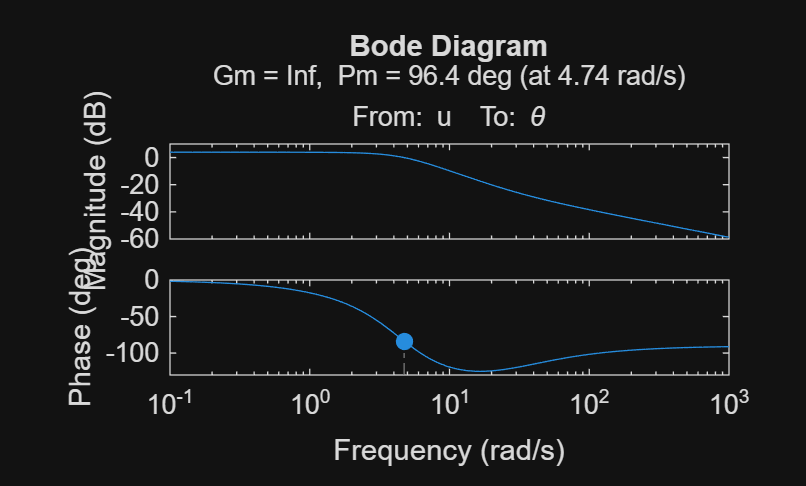

figure;
margin(sys_tf21);

## Calculate Derivative Filter Value

wn = damp(sys_tf21);
tau_d = 1/(10*wn(1));
fprintf("Derivative filter time constant: %f\n", tau_d);

Derivative filter time constant: 0.022046


G = sys_tf21;
H = 1;
opts = pidtuneOptions('DesignFocus','reference-tracking');
wc = 10;  % example rad/s
C = pidtune(G,'PID',wc,opts)


C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 3.06, Ki = 5.68, Kd = 0.0525
 
Continuous-time PID controller in parallel form.


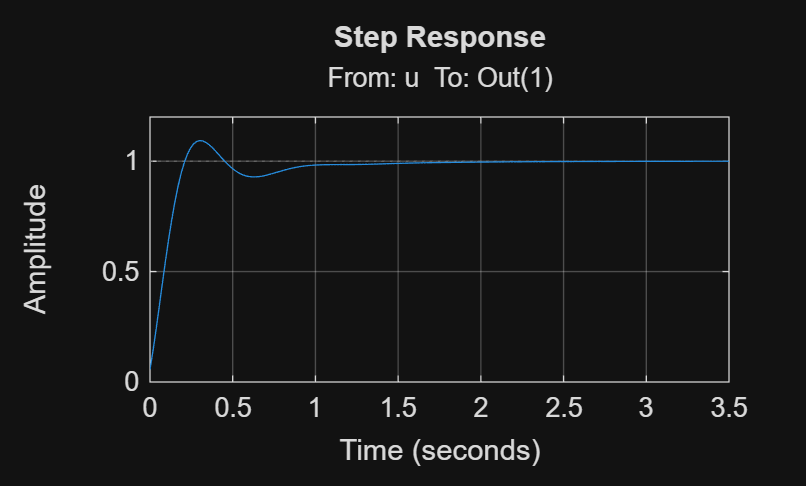

T = feedback(C*G, 1);
step(T), grid on


p = -45;

PM_target = 65;


Kp = 15;
Ki = 23;
Kd = 0.1;

% Build controller + show closed-loop step
s = tf('s');
D   = Kp + Ki/s + Kd * (-p*s/(s - p));     % same form as tuner
D = pid(Kp, Ki, Kd, tau_d)


D =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 15, Ki = 23, Kd = 0.1, Tf = 0.022
 
Continuous-time PIDF controller in parallel form.



Tcl = feedback(G*D, H);

% Verifying PM
L = G*D*H;
[~, PM] = margin(L);
fprintf('Phase margin: PM = %.2f deg (target %.2f)\n', PM, PM_target);

Phase margin: PM = 62.76 deg (target 65.00)


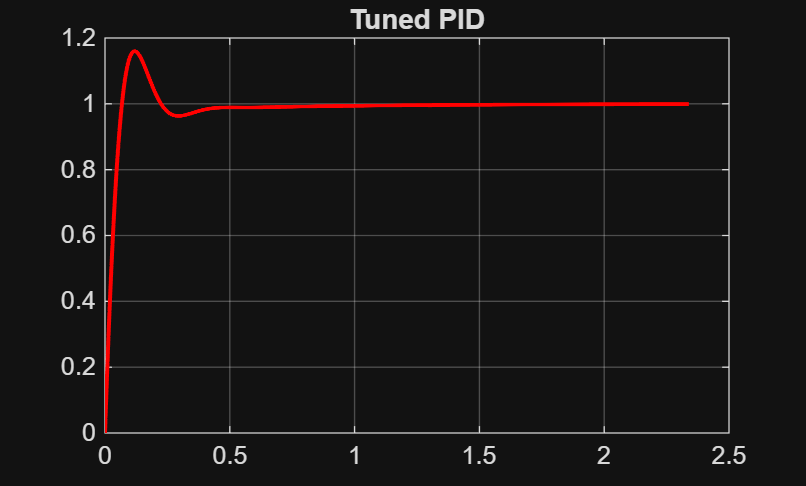


% Use 0-based time axis
t_plot = t - t(1);

% Get step response
y_found = step(Tcl, t_plot);

% Plotting tuned PID
figure;
plot(t_plot, y_found, '-r', 'LineWidth', 1.5);
title('Tuned PID');
grid on;


% Step response metrics
info = stepinfo(Tcl, 'RiseTimeLimits', [0 1]);
Ess  = abs(1 - dcgain(Tcl))*100;
fprintf('Closed-loop metrics: Ts=%.4f s, OS=%.2f%%, Tr=%.4f s, Ess=%.3f%%\n', ...
    info.SettlingTime, info.Overshoot, info.RiseTime, Ess);

Closed-loop metrics: Ts=0.3847 s, OS=15.98%, Tr=0.0679 s, Ess=0.000%


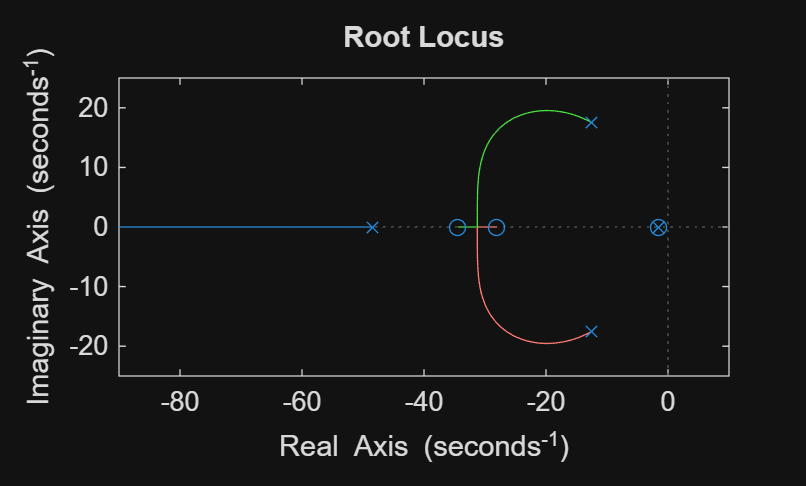


figure;
rlocusplot(Tcl);

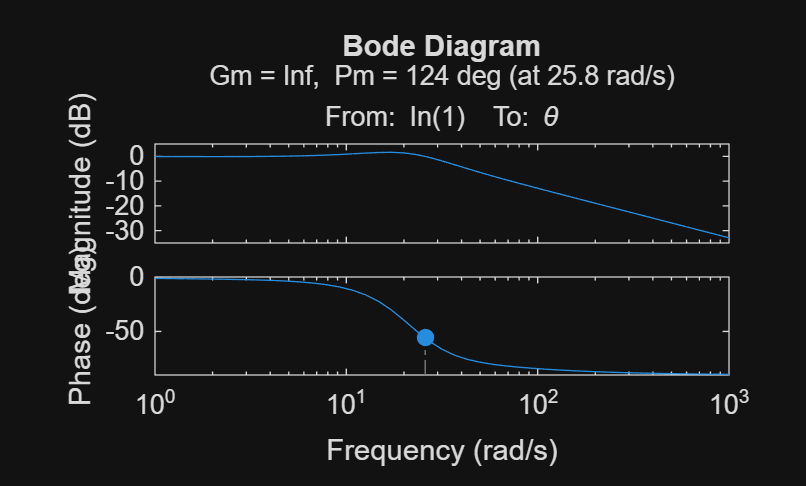

figure;
margin(Tcl);

## Tuning the Gains

G = sys_tf21;     % use your chosen plant model
H = 1;            % unity feedback

% Target RCGs
Ts_target  = 0.10;   % seconds
Tr_target = 0.05;    % seconds
OSu_target = 10;     % percent overshoot
Ess_target = 0.05;      % percent steady-state error
PM_target = 70;      % phase margin

% Derivative filter pole (must be negative)
p = -45;            % try -80 to -800 depending on noise / aggressiveness

% Initial guess (seed)
% using pid tune as a starting point
try
    C0 = pidtune(G, "PID");  % Control System Toolbox
    KIN.K  = 1;
    KIN.Kp = C0.Kp;
    KIN.Ki = C0.Ki;
    KIN.Kd = C0.Kd;
catch
    % fallback guess
    KIN.K  = 1;
    KIN.Kp = 1;
    KIN.Ki = 1;
    KIN.Kd = 0.01;
end

% Run tuner
Kbest = heurRCGTune_PID(KIN, Ts_target, Tr_target, OSu_target, Ess_target, PM_target, p, G, H);

Kp = Kbest(1); Ki = Kbest(2); Kd = Kbest(3);
fprintf('\nTUNED GAINS:\nKp = %.6g\nKi = %.6g\nKd = %.6g\n', Kp, Ki, Kd);

% Build controller + show closed-loop step
s = tf('s');
D   = Kp + Ki/s + Kd * (-p*s/(s - p));     % same form as tuner
Tcl = feedback(G*D, H);

% Verifying PM
L = G*D*H;
[~, PM] = margin(L);
fprintf('Phase margin: PM = %.2f deg (target %.2f)\n', PM, PM_target);

% Use 0-based time axis
t_plot = t - t(1);

% Get step response
y_found = step(Tcl, t_plot);

% Plotting tuned PID
figure;
plot(t_plot, y_found, '-r', 'LineWidth', 1.5);
title('Tuned PID');
grid on;

% Step response metrics
info = stepinfo(Tcl, 'RiseTimeLimits', [0 1]);
Ess  = abs(1 - dcgain(Tcl))*100;
fprintf('Closed-loop metrics: Ts=%.4f s, OS=%.2f%%, Tr=%.4f s, Ess=%.3f%%\n', ...
    info.SettlingTime, info.Overshoot, info.RiseTime, Ess);

## Plotting the experimental data, tuned, and untuned PID

y_untuned = step(sys_tf21, t);
y_tuned = step(Tcl, t);

figure; hold on;
plot(t, y_untuned, '--r', 'LineWidth', 1.5);
plot(t, y_tuned, '-b', 'LineWidth', 1.5);
grid on;

xlabel('Time (s)');
ylabel('Output');
title('Untuned vs Tuned Closed-Loop');
legend('Experimental Data', 'Tuned PID');
